# Topotoolbox introduction to importing and visualizing data

Note: much of this portion of the practical is taken from Topotoolbox Users Guide 1. The user guides can be found under "help" in your TopoToolbox folder. Before running a script, I like to clear the variable space, command window, and all figures. This helps avoiding problems with variables from things you ran before, and ensures a clean start.

clc
clear
close all

### load the data using the GRIDobj function

TopoToolbox 2 reads the ESRI ascii grid format and single band geotiffs into an instance of GRIDobj. Note that in TopoToolbox your DEM is assumed to be in a projected coordinate system (e.g. UTM WGS84) and that elevation and horizontal coordinates are in meter units. Let's load our example DEM from the Hartz mountains in Germany.

DEM = GRIDobj('Hartz_utm.tif');

The variable DEM is now an instance of the class "GRIDobj". DEM has various properties that contain the gridded data and information on the spatial referencing of the grid. Let's just type the name of the variable to check out the fields within the GRIDobj.

DEM

The data is stored in the property .Z. You can access it using linear indexing, subscripts or logical indexing analogous to standard Matlab matrices and arrays. E.g. the upper-left 5x5 pixel in the grid can be accessed by following command.

DEM.Z(1:5,1:5)

You can also access other data in the GRIDobj. For example, you might want to know the cellsize of your DEM, for which you can use the dox indexing.

DEM.cellsize

GRIDobj is associated with various methods. Some of these methods overwrite existing built-in functions (e.g. +, -, isnan) or functions that ship with previous versions of TopoToolbox (e.g. gradient8, curvature, fillsinks). Here is an overview of the methods (functions) associated with GRIDobj

methods GRIDobj

### Visualize DEM

Matlab provides numerous ways to display gridded data (images). Among these are imagesc, surf, pcolor, imshow, etc. TopoToolbox overwrites only imagesc and surf

imagesc(DEM)

Note that the axes contain the x and y coordinates.

Another useful function is imageschs which displays an instance of GRIDobj and overlays it with a hillshade derived from the DEM. A hillshade shadows the topography and gives the appearance of 3D 

imageschs(DEM)

### Topographic attributes

Topographic attributes are derivatives obtained from a DEM such as slope, local relief, or curvature. Local relief is the maximum difference in elevation between pixels within a certain radius.

- gradient8 -> calculates the gradient in 8 possible directions for each cell

- curvature -> the second derivative of a DEM.

- roughness -> allows you calculate various roughness indices 

- aspect -> slope exposition azimuth

- hillshade -> generates a hillshade from your DEM

- and many more...

now let's create a slope map from our DEM

slope = gradient8(DEM)     % creates a GRIDobj, with highest slope of the 8 possible directions for every pixel

and you can visualize the slope map with a hillshade overlay. Also, let's add a label for the colorbar. The help of imageschs tells you how to do this.

imageschs(DEM,slope,'colorbarylabel','slope')

While it is useful to have the slope grid in terms of m/m, it is often more intuitive to have the slope grid in terms of degrees. So let's recast out slope GRIDobj in terms of degrees. How do we do this? Check out the help of the gradient8 function by right-clicking it and either open gradient8 directly or opening the gradient8 help. In the help you should find the input descritption and be able to modify the line below

slope   % calculate slope in degree

Now plot your new slope data using imageschs and add a label for the colorbar and add some saturation to the colorbar to improve visibility

Now we let's calculate local relief and aspect, too. The function for local relief is called "localtopography", and the radius we want to use for calculation is 500 m. You can double click the function name to check the help and find out the syntax for running it. Run the aspect function, too, to make an aspect raster.

locrel 
aspect_grid 

Now, lets's use the subplot function to subplot all data next to each other. We have a DEM, slope, local relief, and aspect raster. So, we need a 2x2 plot. Use the title function to label your plots. Let's also explore the use of different color maps. I'll demonstrate this here with the DEM.

figure()
set(gcf,'Units','normalized','Position',[0 0 1 1]); 
subplot(2,2,1)
imageschs(DEM,[],'colormap',landcolor,'colorbarylabel','meter')
title('DEM')
subplot(2,2,2)
% plot the slope here
% dont forget the title

% plot local relief

% plot aspect

What geomorhologic features of the Hartz can you directly notice in the slope and local relief maps?

Check out how the aspect plot highlights lineaments in the landscape. These can be ralted to features like faults or lithologic contacts. Take a look at geologic map of the Hartz below. Indeed the WNW-ESE striking features seem fault related, whereas the ths SW-NE striking features seem realted to lithologic contacts, dykes, and folding of the basement rocks.

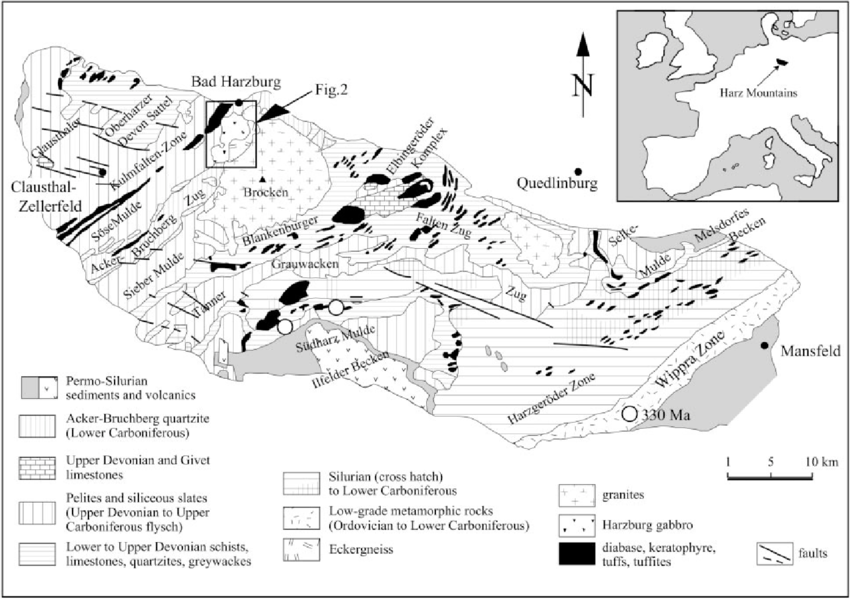

One more thing. Why did I tell you to use 500m for the local relief calculation? This is a pretty common radius for the relief calculation that typically captures the variability on the scale of the river drainage network. Use the slider below to see how different radius values change the local relief map. The larger the radius the larger, the broader the features you're resolcing. Also, you might notice you the calculation time increases when you increase the radius.

radius = 1900
locrel = localtopography(DEM,radius);
figure()
imageschs(DEM,locrel)

### Export

Export an instance of GRIDobj to the disk. TopoToolbox ships with two functions for writing instances of GRIDobj so that they can be read by standard GIS software such as QGIS etc.

GRIDobj2ascii(DEM,'test.txt');

Note that DEM, slope, etc are all GRIDobjects and can be exported

GRIDobj2geotiff(slope,'test_slope.tif');